# Train Topographic Map Network

Live script used to train topographic map network

tic
path = pwd;
cd ../../eeglab/ % replace with EEGlab path
eeglab
close
cd (pwd)

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\nonun\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.7 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.6 available
EEGLAB: adding "xdfimport" v1.18 (see >> help eegplugin_xdfimport)


load("chlocs2.mat")
%Make TopoDatastore
fol = "D:\3minSept22";
ds_all = TopoDatastore(fol,[],channel_locations);
toc

Used Matched Age and Gender subjects/sessions of HEA and STR

[HEA,STR,TBI] = MatchSubjects();
s = split(HEA.Location,'\');

Elapsed time is 256.766027 seconds.


# HEA subjects/sessions: 595/629
# STR subjects/sessions: 527/585
# TBI subjects/sessions: 552/629


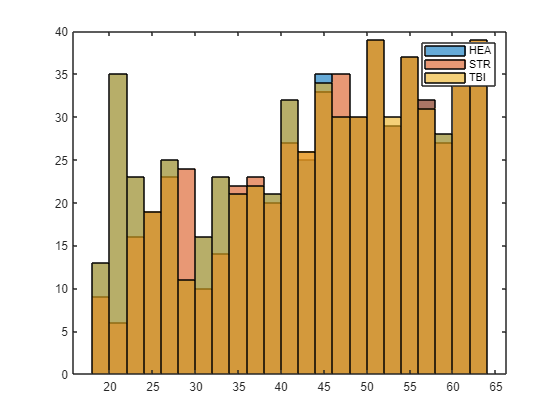

s = string(s(:,9));
s = split(s,'.');
HEA = s(:,1);

s = split(STR.Location,'\');
s = string(s(:,9));
s = split(s,'.');
STR = s(:,1);
s = split(TBI.Location,'\');
s = string(s(:,9));
s = split(s,'.');
TBI = s(:,1);

Check for overlaps

f = string(ds_all.Datastore.Files);
in_HEA = [];
in_STR = [];
in_TBI = [];
for i = 1:length(f)
    for j = 1:length(HEA)
        if contains(f(i),HEA(j))
            in_HEA = [in_HEA i];
            break
        end
    end
    for j = 1:length(STR)
        if contains(f(i),STR(j))
            in_STR = [in_STR i];
            break
        end
    end
    for j = 1:length(TBI)
        if contains(f(i),TBI(j))
            in_TBI = [in_TBI i];
            break
        end
    end
end
%in_TBI = find(ds_all.Labels == "TBI")';
in = [in_HEA, in_STR, in_TBI];
ds_match = subset(ds_all,in);
%ds_match_test = subset(ds_test,in);

Set aside >=50 samples for IV 

c = string(categories(ds_match.Labels));
numsub = max(50,floor(min(countcats(ds_match.Labels))*.2));
disp("Using " + numsub + " for IV.")
in_iv = [];
in_cv = [];
for i = 1:length(c)
    in = find(ds_match.Labels == c(i));
    r = randperm(length(in));
    in_iv = [in_iv; in(r(1:numsub))];
    in_cv = [in_cv; in(r(numsub+1:end))];

Using 569 for IV.


end
X_Train=subset(ds_match,in_cv);
X_Test=subset(ds_match,in_iv);

Layers

numclasses = X_Train.NumClasses;
layers = [
    imageInputLayer([134 134 6],"Name","imageinput","Normalization","none")
    convolution2dLayer([3 3],32,"Name","conv_1")
    maxPooling2dLayer([3 3],"Name","maxpool_1","Stride",[1 1])
    reluLayer("Name","relu_1")
    convolution2dLayer([3 3],32,"Name","conv_2")
    maxPooling2dLayer([3 3],"Name","maxpool_2","Stride",[2 2])
    reluLayer("Name","relu_2")
    convolution2dLayer([3 3],64,"Name","conv_3")
    maxPooling2dLayer([3 3],"Name","maxpool_3","Stride",[1 1])
    reluLayer("Name","relu_3")
    convolution2dLayer([3 3],128,"Name","conv_4")
    maxPooling2dLayer([3 3],"Name","maxpool_4","Stride",[2 2])
    reluLayer("Name","relu_4")
    fullyConnectedLayer(100,"Name","Largefc")
    fullyConnectedLayer(numclasses,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];
figure;
plot(layerGraph(layers));

## Generate Local Data

6GB RAM needed. Only need to run one time.

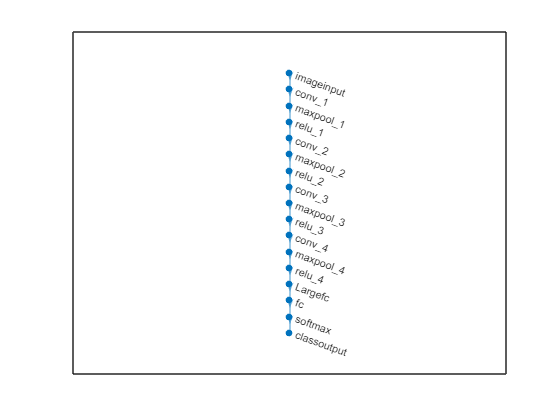

% y = zeros(134,134,6,length(X_Train.Labels)); %~6Gb
% X_Train.MiniBatchSize = 1;
% reset(X_Train)
% for i = 1:length(X_Train.Labels)
%     temp = read(X_Train);
%     y(:,:,:,i) = temp.Predictors{1};
% end
% v = zeros(134,134,6,length(X_Test.Labels)); %~6Gb
% X_Test.MiniBatchSize = 1;

% reset(X_Test)
% for i = 1:length(X_Test.Labels)
%     temp = read(X_Test);
%     v(:,:,:,i) = temp.Predictors{1};
% end
% save('TopoData.mat',"v","y","X_Train","X_Test",'-v7.3');

Due to the large file size, an example file is not included for this dataset. To reproduce use the code above.

load('TopoData.mat');

## Run Network

% gpuDevice(1);
% miniBatchSize=200;
% opts=trainingOptions("adam","Plots","training-progress","ExecutionEnvironment","gpu", ...

%     "Shuffle","every-epoch","MiniBatchSize",miniBatchSize,"MaxEpochs",300,...
%     "InitialLearnRate",0.001,"LearnRateSchedule","piecewise","LearnRateDropPeriod",100,..."GradientThreshold",2,...
%     "OutputNetwork","best-validation-loss","ValidationData",{v,X_Test.Labels},"ValidationFrequency",100,...
%     "ValidationPatience",20,"L2Regularization",.001);
% net=trainNetwork(y,X_Train.Labels,lgraph_1,opts);

## Basic Architecture

load("Topo_BasicNet.mat","net3")
basic3 = MdlResults(net3,v,X_Test.Labels);
classify(basic3);
metrics(basic3);

## Supporting Functions

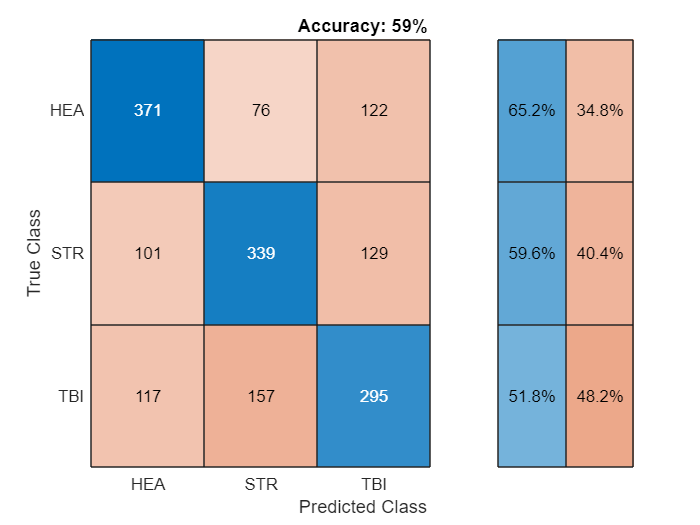

function [CV,IV]=pathname(path,C)
if nargin<2
    C=["HEA","STR","TBI"];
end
d=load("CVIVsplit_LSTM.mat");
j=1;
j2=1;
for k=1:length(C)
    x=d.(C(k)+"_TCV");
    y=d.(C(k)+"_TIV");
    %CV=cell(1,height(x));
    %IV=cell(1,height(y));
    for i=1:height(x)
        if length(C)>1
            CV{j}=fullfile(path,C(k), ...
                [eightdigit(x.Subject(i)),'_',x.Session(i),'_',num2str(x.Date.Year(i)),'_', ...
                doubledigit(x.Date.Month(i)),'_',doubledigit(x.Date.Day(i)), ...

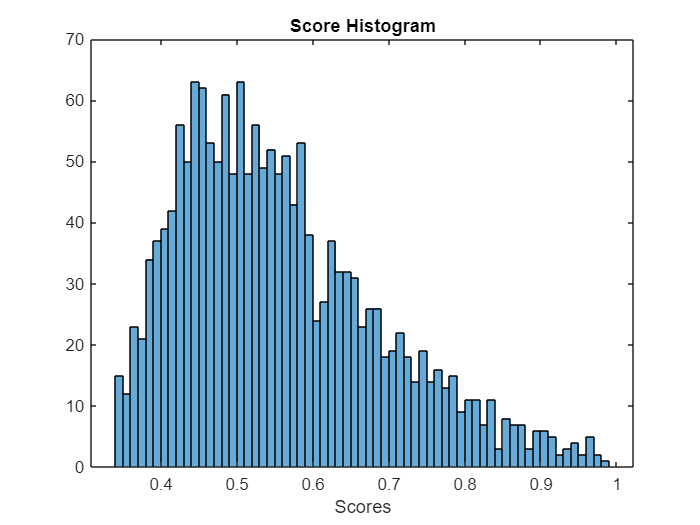

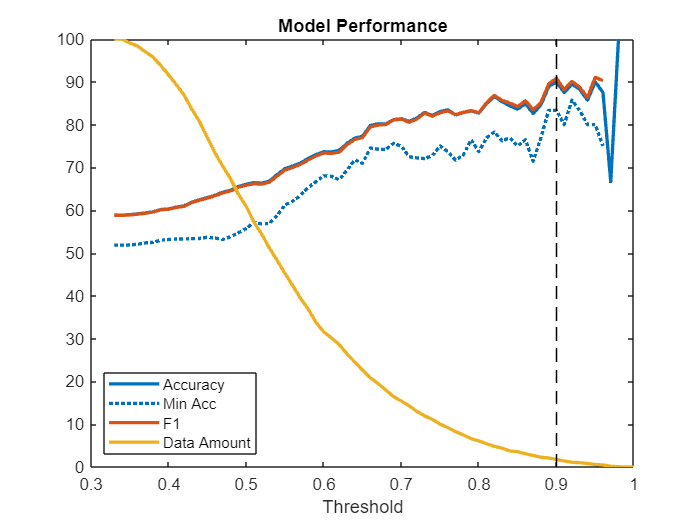

Data Remaining: 0.017575


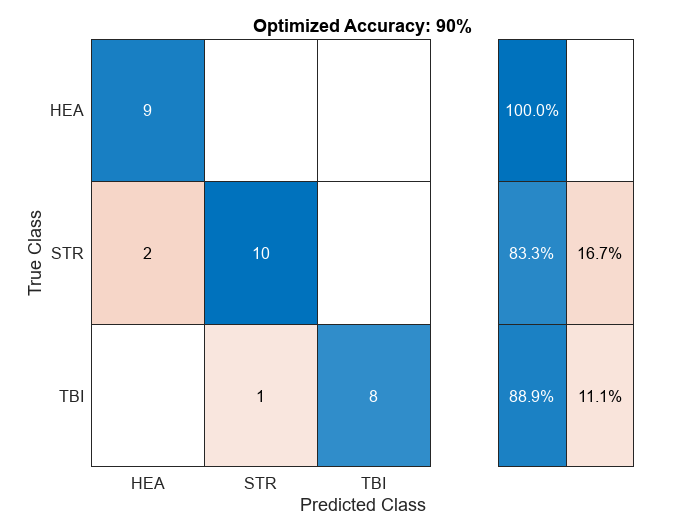

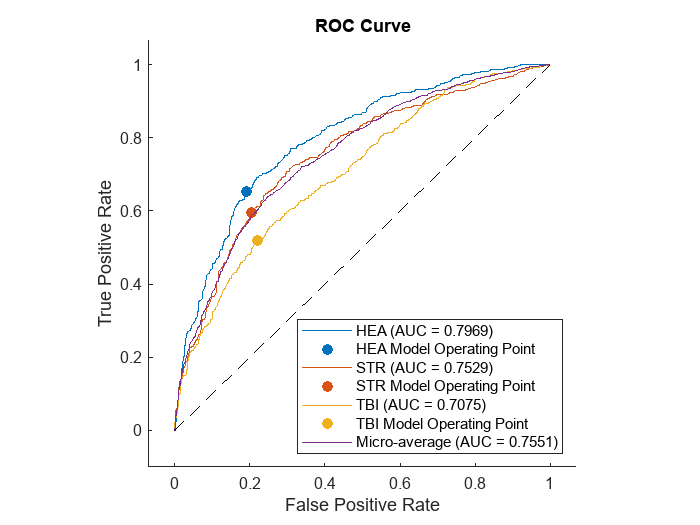

                '-',num2str(x.Min(i)),'.mat']);

        else
            CV{j}=fullfile(path,C(k),eightdigit(x.Subject(i)), ...
                [x.Session(i),'_',num2str(x.Date.Year(i)),'_', ...
                doubledigit(x.Date.Month(i)),'_',doubledigit(x.Date.Day(i)), ...
                '-',num2str(x.Min(i)),'.mat']);
        end
        j=j+1;
    end
    for i=1:height(y)
        if length(C)>1
            IV{j}=fullfile(path,C(k), ...
                [eightdigit(x.Subject(i)),'_',x.Session(i),'_',num2str(x.Date.Year(i)),'_', ...
                doubledigit(x.Date.Month(i)),'_',doubledigit(x.Date.Day(i)), ...
                '-',num2str(x.Min(i)),'.mat']);
        else
            IV{j}=fullfile(path,C(k),eightdigit(x.Subject(i)), ...
                [x.Session(i),'_',num2str(x.Date.Year(i)),'_', ...
                doubledigit(x.Date.Month(i)),'_',doubledigit(x.Date.Day(i)), ...
                '-',num2str(x.Min(i)),'.mat']);
        end
        j2=j2+1;
    end
end
    function y=doubledigit(x)
        y=num2str(x);
        if length(y)<2
            y=['0',y];
        end
    end
    function y=eightdigit(x)
        y=num2str(x);
        if length(y)<8
            y=[repelem('0',8-length(y)),y];
        end
    end
end
function in=MatchSubject(Files,CV)
sFiles=SubSplit(Files);
sCV=unique(SubSplit(CV));
in=ismember(sFiles,sCV);
    function s=SubSplit(x)
        if size(x,1)==1
            x=x';
        end
        s=split(x,'\');
        s=s(:,end);
        s=split(s,'_');
        s=s(:,1);
    end
end

function [y,labels] = TemporalSplit(ds,fs)
reset(ds);
ds.MiniBatchSize = 1;
y = cell(ds.NumObservations*5,1);
for i = 1:ds.NumObservations
    T = read(ds);
    x = cell2mat(T.predictors);
    t = 1 + 5*(i-1);
    labels(t:t+4) = T.responses;
    y{t} = x(:,1:90*fs);
    y{t+1} = x(:,(90*fs+1):end);
    for j = 2:4
        r = randi(90*fs-2)+1;
        y{t+j} = x(:,r:r+(90*fs-1));
    end
end
end

function [YPred,scores] = ClassifyTest(net,v,labels)
[YPred,scores] = classify(net,v,"ExecutionEnvironment",'cpu');
accuracy = round((sum(YPred == labels)./numel(labels))*100);

confusionchart(labels, YPred, "RowSummary", "row-normalized");
title("Accuracy: " + accuracy' + "%")
end

function rocObj = AUC(scores,labels,YPred)
figure;
histogram(max(scores,[],2),.34:.01:.99)
title("Score Histogram")
xlabel Scores
acc=[];
minacc=[];
sens=[];
prec=[];
F1=[];
numData = [];
t=.33:.01:1;
for i = t
    score_in = max(scores,[],2)>i;
    C=confusionmat(labels(score_in), YPred(score_in));
    acc = [acc 100*((C(1,1)+C(2,2)+C(3,3))/(sum(C,'all')))];
    minacc = [minacc min(100*[C(1,1) C(2,2) C(3,3)]./(sum(C,2)'),[],"includenan")];
    sens = [sens 100*(mean(diag(C)./sum(C,2)))];
    prec = [prec 100*(mean(diag(C)./sum(C,1)'))];
    F1 = [F1 (2*sens(end)*prec(end))/(sens(end)+prec(end))];
    numData = [numData 100*sum(score_in)/length(scores)];
end
E = (2*F1 + numData + acc + minacc)/5;
[~,a] = max(E);
conf = t(a);
c = colororder();
figure;
plot(t,acc,'LineWidth',2,'Color',c(1,:))
hold on
plot(t,minacc,':','LineWidth',2,'Color',c(1,:))
%plot(t,sens,'LineWidth',2,'Color',c(2,:))
%plot(t,prec,'LineWidth',2,'Color',c(3,:))
plot(t,F1,'LineWidth',2,'Color',c(2,:))
plot(t,numData,'LineWidth',2,'Color',c(3,:))
plot([conf conf],[0 100],'k--')
legend(["Accuracy","Min Acc","F1","Data Amount"],'Location','southwest')
title("Model Perfromance")
xlabel Threshold
score_in = max(scores,[],2)>conf;
disp("Data Remaining: " + num2str(sum(score_in)/length(scores)))
accuracy = round((sum(YPred(score_in) == labels(score_in))./numel(labels(score_in)))*100);
figure;
confusionchart(labels(score_in), YPred(score_in), "RowSummary", "row-normalized");
title("Optimized Accuracy: " + accuracy' + "%")
rocObj = rocmetrics(labels,scores,["HEA","STR","TBI"]);
plot(rocObj,"AverageROCType","micro")
end